# **LAB:  Bearing Fault Monitoring and RUL Estimation**

**Name: AN GYEON HEAL**

**ID: 21900416**

**Date: 2024-09-24**

**Due in 1 week**

## **Instruction**

In this LAB, you are required to create a simple code for Fault Monitoring and RUL estimation

You can refer to RUL estimation tutorial codes and related papers

**Fault Monitoring**

- Detect Fault Status

- Display WARNING MESSAGE

**RUL Estimation **

- Estimate RUL similar to Tutorial codes

- The end of Life can be assumed when the repair is done

## Dataset

Raw Dataset of Bearing Velocity measured that shows a Bearing Life cycle before the repair is done. Also the velocity measurement after the repair is provided.

**Download** bearing  dataset for this lab: [[Download here](https://drive.google.com/file/d/1L9iz34MI8v469J30SCM6_38TT7TICXrX/view?usp=share_link)]

Using the given dataset, develop simple program for

- Bearing velocity measured 24 times per day

- Each measurement is L=8192 with Fs=2560Hz  

- Measurement for consecutive days until repair is done

First visualize the vibration signals in the time domain. 

clear; close all; clc;

load("RULdata/bearing-vel-fulldata-rul.mat");
% rows: vel measurements // cols: measurement time 
% idx_repair = 1431;

bearing=bearingFulldata(:,1:idx_repair);
bearingNew=bearingFulldata(:,idx_repair+1:end);

% Data Length for each measurement
% L=8192
L=length(bearing(:,1))
% Sampling Frequency
fs = 2560;
ts = 1/fs;
t = 0:ts:ts*(L-1);

% Day(time) unit upto repair
dataN=(length(bearing(1, :)));
d = (0:1:dataN)/24;

Plotting bearing velocity raw data

- Initial state:  Day=0 

- Just before repair:  Day=59

- After repair:  Day=60

idx1 = 1;   idx2 = idx_repair;    idx3 = 1;

figure
subplot(3, 1, 1);       plot(t, bearing(:, idx1));
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(day 1)');
subplot(3, 1, 2);       plot(t, bearing(:, idx2));
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(day 59)');
subplot(3, 1, 3);       plot(t, bearingNew(:, idx3));
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(Repaired, day 60)');

## **Data Exploration and Preprocessing**

You need to explain the process cleary and analyze the results

figure

L = 8192

hold on;
tstart = 0;
for day = 1:2104
    t = tstart + (1:length(v))/fs;
    plot(t, bearingFulldata(:,day))
end
hold off;

## **Feature Extraction and Analysis**

You need to explain the process cleary and analyze the results

%%% YOUR CODE GOES HERE


## **Selection of Features**

You need to explain the process cleary and analyze the results

%%% YOUR CODE GOES HERE


## Fault Monitoring and Warning

You need to explain the process cleary and analyze the results

%%% YOUR CODE GOES HERE


## RUL Estimation

You need to explain the process cleary and analyze the results

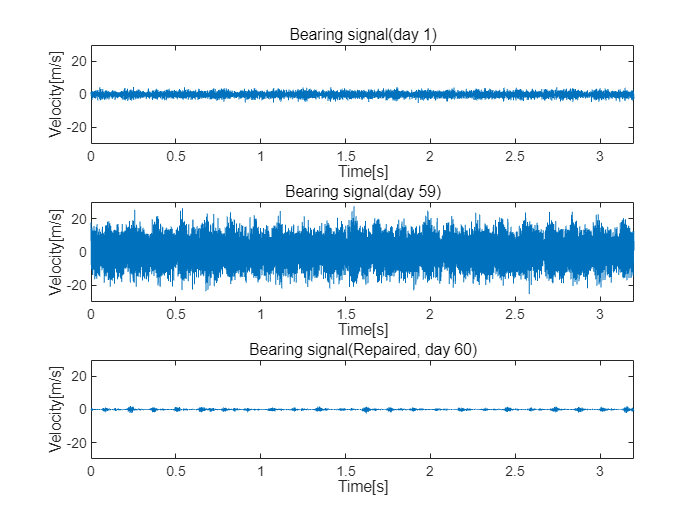

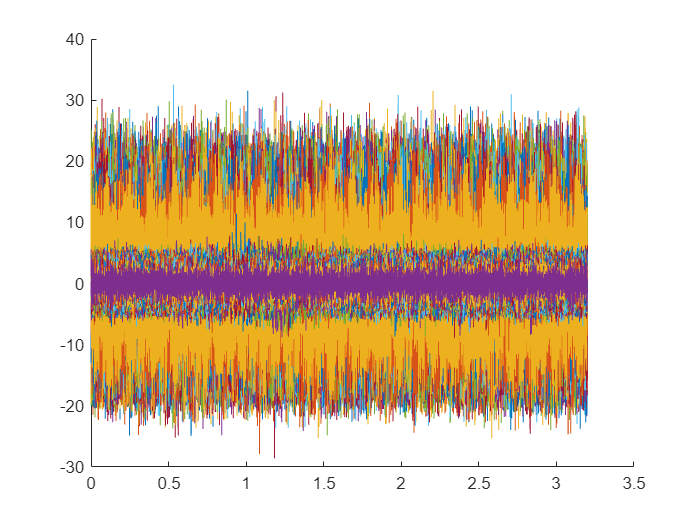

%%% YOUR CODE GOES HERE


## Discussion 

Discussion goes here

## Reference